## MN P3 ExParcial 1Q 2024-25 

### Question 4

Consider a clamped at ground pillar shaped as a truncated straight pyramid, height $15000\; \text{mm}$, dimensions $1500\times 500\; \text{mm}$ at its basis, and $500 \times 500\; \text{mm}$ at its top face. The Young modulus of the material and its specific weight are $28.0\; \text{GPa}$, and $25\times 10^{-9}\; \text{kN/mm}^{3}$ respectively. Further ---due to the charge it supports---the pillar is under a contraction stress of $33\times 10^{-6}\; \text{GPa}$, acting on its upper face.

    Take a mesh of $55$ linear elements with equispaced nodes, numbered upwards and in ascending order; apply the FEA to find the nodes' displacements and answer the questions that follow below.

    **Hint 1:*** In this case*, the area of the transverse section, $A(x)$, varies linearly with the height $x$; more precisely, it is an affine function of the form $A(x) = \alpha x + \beta$, $0\le x\le 15000$, for the appropriate values of $\alpha$ and $\beta$.

    **Hint 2: **It is advisable to use the same units as those that appear in the statement; in this way the displacements will be obtained directly in mm.

%
%fem1DLiveScript.m
%
clearvars
close all

### Computation of the displacements

%Càlcul de les u's

%Real constants
E = 28.0;                          %GPa (= 28.0 kN/mm^2) 
w = 25.0e-9;                       %kN/mm^3
P = 33.0e-6;                       %GPa (= 24.0e-6 kN/mm^2) {24, 27, 30, 33, 36}e-6 kN/mm^2

%Geometry
l = 0.5e3;                         %mm
L = 1.5e3;                         %mm
H = 15.0e3;                        %mm height
r = 0.5e3;                         %mm width

xp = H/2;

nDiv = 55;                         %Number of divisions = number of elements

nodes = linspace(0, H, nDiv+1)';   %Position of the nodes
numNodes = size(nodes, 1);         %Number of nodes
h = nodes(2) - nodes(1);           %h: lenght of the nodes

elem = [1:numNodes-1;
        2:numNodes]';              %Connectivity matrix  
numElem = size(elem, 1);           %Number of elements 

%Compute the nodes of the elements to which point xp belongs
%nod1 = ceil(xp / h); nod2 = nod1+1;

%A(x) = alpha x + beta
%A(0) = beta = rL
%A(H) = alpha*H + rL = rl <==> alpha = r*(L-l)/H

alpha = r*(l-L)/H;
beta = r*L;

stiffnessMatrix = @(x1, x2) (beta + 0.5*alpha*(x1+x2))*[1 -1; -1 1]/(x2-x1);
forceVector = @(x1,x2) (x2-x1)*(beta*[1;1]/2 + alpha*[2*x1+x2; x1+2*x2]/6);

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);
u = zeros(numNodes,1);

for e = 1:numElem

    rows = [elem(e,1); elem(e,2)];
    cols = rows;

    x1 = nodes(rows(1)); x2 = nodes(rows(2));

    Ke = E*stiffnessMatrix(x1,x2);
    K(rows,cols) = K(rows,cols) + Ke;

    Fe = forceVector(x1,x2);
    F(rows) = F(rows) + Fe;

end

%Boundary conditions B.C.
fixedNodes = 1;
freeNodes = setdiff(1:numNodes, fixedNodes);
%Natural B.C.
Q(numNodes) = -P*r*l; 

%Essential B.C.
u(1) = 0.0;

%Reduced system
Fm =  -w*F(freeNodes) + Q(freeNodes) - K(freeNodes, fixedNodes) * u(fixedNodes);
Km =  K(freeNodes, freeNodes);

%Solution of the reduced system
um = Km\Fm;
u(freeNodes) = um; solArray = [(1:numNodes)', nodes, u];


Table with the displacements at the nodes

format short e
format compact

%table with the displacement at the nodes
solTable = array2table(solArray, 'VariableNames',{'Nod.','X','U'})

solTable = 56×3 table
       Nod.           X              U     
    __________    __________    ___________
    1.0000e+00    0.0000e+00     0.0000e+00
    2.0000e+00    2.7273e+02    -2.5244e-03
    3.0000e+00    5.4545e+02    -5.0132e-03
    4.0000e+00    8.1818e+02    -7.4663e-03
    5.0000e+00    1.0909e+03    -9.8836e-03
    6.0000e+00    1.3636e+03    -1.2265e-02
    7.0000e+00    1.6364e+03    -1.4611e-02
    8.0000e+00    1.9091e+03    -1.6920e-02
    9.0000e+00    2.1818e+03    -1.9194e-02
    1.0000e+01    2.4545e+03    -2.1431e-02
    1.1000e+01    2.7273e+03    -2.3632e-02
    1.2000e+01    3.0000e+03    -2.5797e-02
    1.3000e+01    3.2727e+03    -2.7925e-02
    1.4000e+01    3.5455e+03    -3.0017e-02
    1.5000e+01    3.8182e+03    -3.2073e-02
    1.6000e+01    4.0909e+03    -3.4091e-02

Plot the displacements ($x$ v.s. $u$).

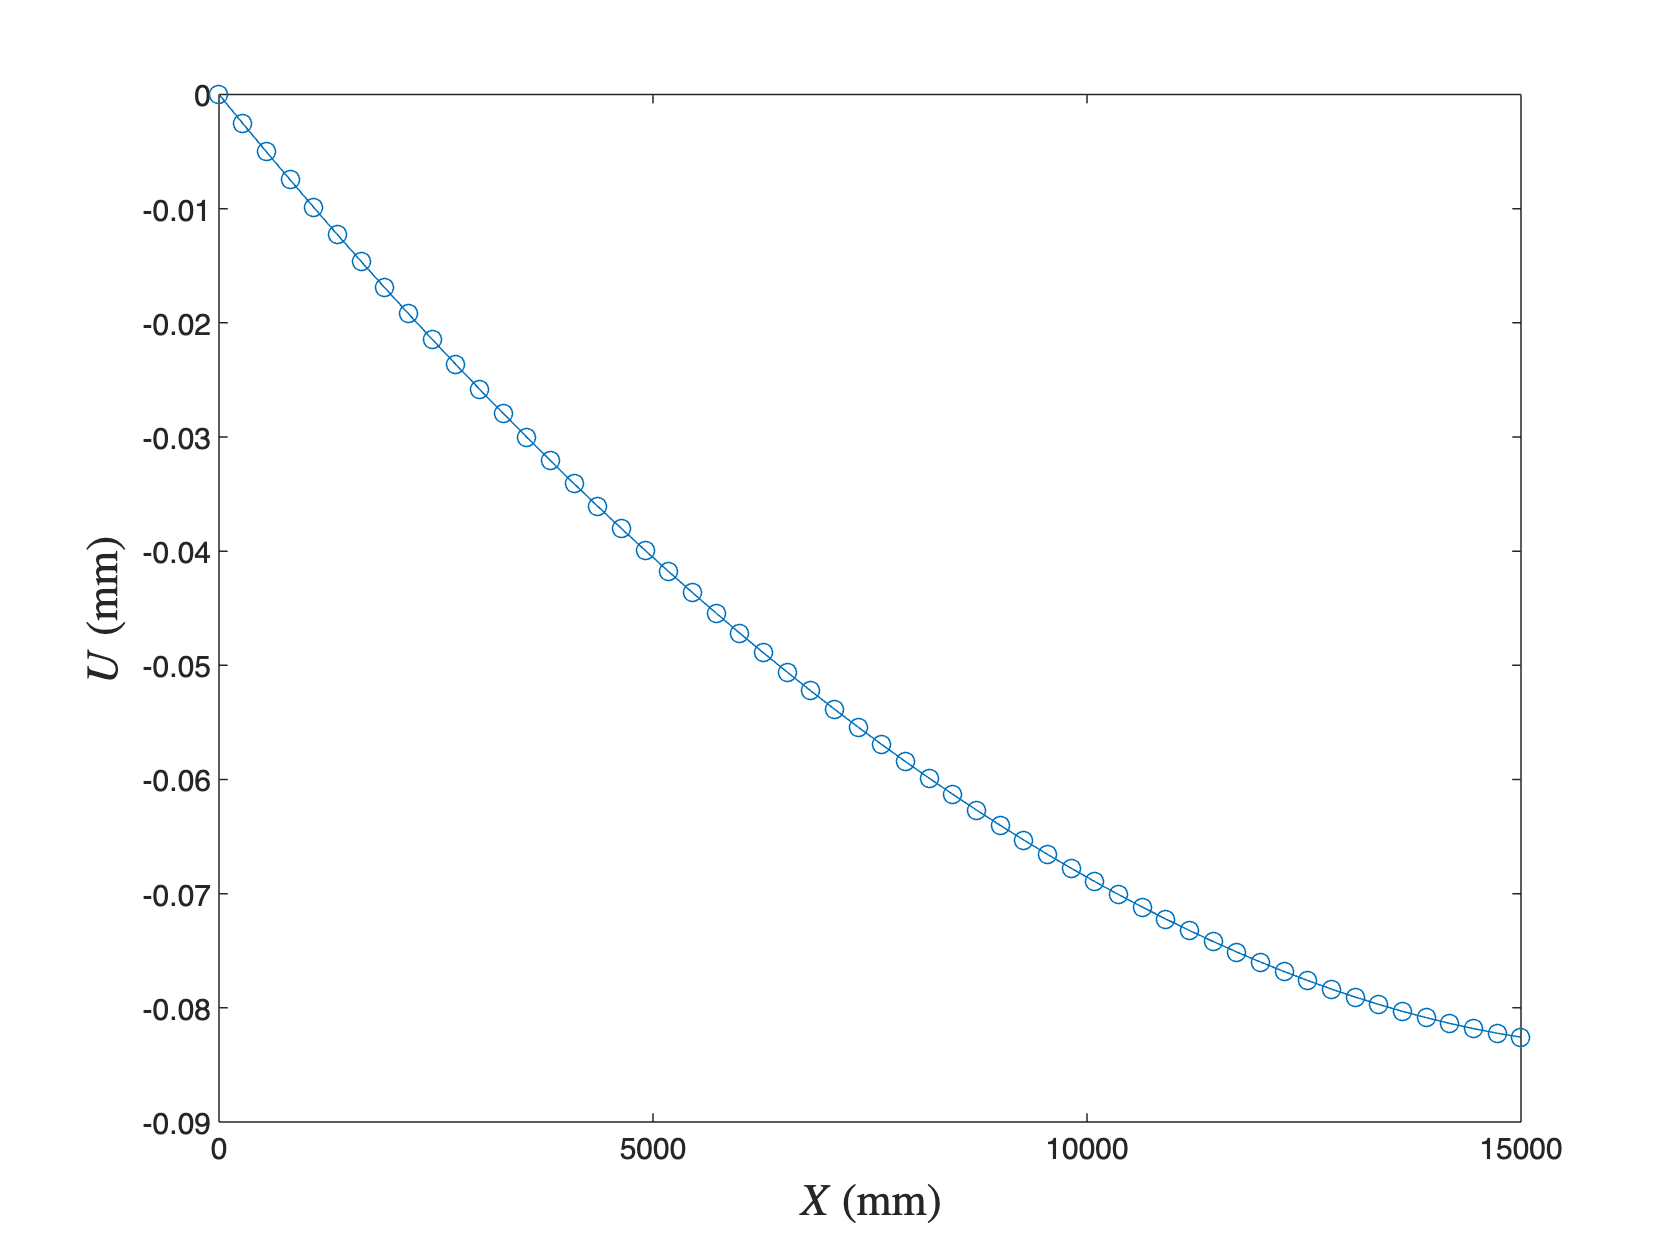

%Plot the displacements
plot(nodes,u,'o-')
xlabel('$X$ (mm)','FontSize',15,'Interpreter','LaTex')
ylabel('$U$ (mm)','Fontsize',15,'Interpreter','LaTeX')

### Part (a)

(4 points) The average of nodes' displacement, defined as the sum of all the nodes's diplacement divided by the number of nodes (in mm), is

- -5.3804e-02

- -4.7562e-02

- -5.1662e-02

- Leave it empty (no penalty)

- -5.1080e-02$\surd$

`Hint 3:`` The displacement of the node placed at the column's topmost height is `$u(15000)\approx U_{56} = -8.2573\times 10^{-2}\, \text{mm}$.

#### Solution

`(a) `$\langle u \rangle \approx  -5.1080\times 10^{-2}\, \text{mm}$.

%(a) Avergaged value of u
avgdU = sum(u)/numNodes;
fprintf('(a) <u> %s %10.4e mm. Hint u(%.2f) %s U(%d) = %10.4e mm',...
    char(8776), avgdU, H, char(8776), numNodes, u(end))

(a) <u> ≈ -5.1080e-02 mm. Hint u(15000.00) ≈ U(56) = -8.2573e-02 mm

### Part (b)

(3 points) Uisng linear interpolation to approximate; the displacement (in mm) at the midpoint of the pillar is

- -6.0011e-02

- Leave it empty (no penalty)

- -5.4772e-02

- -5.6178e-02$\surd$

- -5.6411e-02

**Hint 4:** For the linear interpolation, use the  values of the displacement gelened by the FEM at the two nodes of the elment the point is in.

#### Solution

(b) Interpolated value of $u$ at  $x = 7500\;  (\text{mm})$: $u(7500)\approx -5.6178 \times 10^{-2}\; \text{mm}$.

%(b) Interpolated value at the midpoint of the pillar
interpU = interp1(nodes, u, xp);
fprintf('(b) Interpolated value of u at x = %.2f (mm): u(%.2f) %s %10.4e mm\n',...
    xp, xp, char(8776), interpU)

(b) Interpolated value of u at x = 7500.00 (mm): u(7500.00) ≈ -5.6178e-02 mm


### Part (c)

What should be the specific weight of the material for the displacement's linear interpolation at the midpoint (see the **Hint 4**, at the end of the previous question) equals the 50% of the topmost node's displacement? (units in $\text{kN/mm}^{3}$).

- 1.9660e-09$\surd$

- 1.8491e-09

- 1.6036e-09

- 2.0850e-09

- Leave it empty (no penalty)

#### Solution

Find the element the midpoint $x_{p} = 7500$ belongs using $n_{1} = \left\lceil \frac{x_{p}}{h}\right\rceil$,  and $n_{2} = n_{1} + 1$, being $h$ the length of the element, and $\left\lceil\cdot\right\rceil$ defined as:

$\left\lceil x\right\rceil = \min\left\{ z\in\mathbb{Z}: z\ge x\right\}$.

Then,


$$n_{1} = \left\lceil \frac{7500}{1500/55}\right\rceil = \left\lceil\frac{55}{2}\right\rceil = \lceil 27.5\rceil = 28,\qquad n_{2} = n_{1} + 1 = 29.$$


%Compute the nodes of the elements to which point xp belongs
nod1 = ceil(xp / h); nod2 = nod1+1;
fprintf('n1 = %d, n2 = %d', nod1, nod2)

n1 = 28, n2 = 29

If $x_{i}$ is the position of the $i$-th node, $i = 1,\dots,56$, we define $\sigma = \frac{x_{p}-x_{28}}{x_{29}-x_{28}} = \frac{7500 - x_{28}}{x_{29}-x_{28}}$, and then the interpolated value of $u$ at the midpoint, $u_{p}$, is given by $u_{p} = (1-\sigma)u_{28} + \sigma u_{29}$. As we want $u_{p} = \frac{u_{56}}{2}$, this gives us an additional equation, namely,


$$(1-\sigma) u_{28} + \sigma u_{29} - \frac{u_{56}}{2} = 0.$$


    Now, let the vector $\hat{F}\in\mathbb{R}^{56}$ be given by, 


$$\hat{F}^{\top} =
\left(\begin{array}{c}
\hat{F}_{1}\\
\hat{F}_{2}\\
\hat{F}_{3}\\
\vdots\\
\hat{F}_{55}\\
\hat{F}_{56} 
\end{array}\right) =
\left(\begin{array}{c}
 \hat{F}^{1}_{1} \\
 \hat{F}^{1}_{2} + \hat{F}^{2}_{1}\\
\hat{F}^{2}_{2} + \hat{F}^{3}_{1}\\
\vdots\\
\hat{F}^{54}_{2} + \hat{F}^{55}_{1}\\
\hat{F}^{55}_{2}
\end{array}\right),$$


being,


$$\begin{array}{rcl}
\hat{F}^{e}_{1} &\!\!\!\!=\!\!\!\!& \int_{x_{1}^{e}}^{x_{2}^{e}} A(x) \Psi_{1}^{e}(x)\,\mathrm{d} x = \int_{x^{1}_{e}}^{x_{2}^{e}} (\alpha x + \beta)\frac{x-x_{2}^{e}}{x_{1}^{e}- x_{2}^{e}}\mathrm{d} x = \frac{h_{e}}{2}\left(\beta + \alpha\frac{2 x_{1}^{e} + x_{2}^{e}}{3}\right),\\
\hat{F}^{e}_{2} &\!\!\!\!=\!\!\!\!& \int_{x_{1}^{e}}^{x_{2}^{e}} A(x) \Psi_{2}^{e}(x)\,\mathrm{d} x = \int_{x^{1}_{e}}^{x_{2}^{e}} (\alpha x + \beta)\frac{x-x_{1}^{e}}{x_{2}^{e}- x_{1}^{e}}\mathrm{d} x = \frac{h_{e}}{2}\left(\beta + \alpha\frac{x_{1}^{e} + 2x_{2}^{e}}{3}\right),
\end{array}$$


with,


$$\begin{array}{c}
h_{e} = x^{e}_{2} - x^{e}_{1}, \quad e = 1,2,\dots,55,\\
x^{1}_{1} = x_{1},\ x^{1}_{2} = x^{2}_{1} = x_{2},\dots, x^{54}_{2} = x^{55}_{1} = x_{55} ,\ x^{55}_{2} = x_{56},\\
\alpha = -\frac{100}{3},\ \beta = 7.5\times 10^{5} \ \text{(already computed)},
\end{array}$$


and note that, then $F = -w\hat{F}$. Now, we can write the, let's call, the *extended* assembled system, were the unknows are $u_{1},\dots u_{56}, w$; and that holds the above deduced aquation, i.e., $(1-\sigma) u_{28} + \sigma u_{29} - \frac{1}{2} u_{56} = 0$, and an additional equation,


$$\left(
\begin{array}{cccccccc|c}
K_{1,1} & \cdots & K_{1,27} & K_{1,28} & K_{1,29} & K_{1,30} & \cdots & K_{1,56} & \hat{F}_{1}\\
K_{2,1} & \cdots & K_{2,27} & K_{2,28} & K_{2,29} & K_{2,30} & \cdots & K_{2,56} & \hat{F}_{2}\\
K_{3,1} & \cdots & K_{3,27} & K_{3,28} & K_{3,29} & K_{3,30} & \cdots & K_{3,56} & \hat{F}_{3}\\
\vdots & \ddots & \vdots &\vdots & \vdots & \vdots &\ddots & \vdots &\vdots\\
K_{56,1} &\cdots & K_{56,27} & K_{56,28} & K_{56,29} & K_{56,30} &\cdots & K_{56,56} & \hat{F}_{56}\\ \hline
0 & \cdots & 0 & 1-\sigma & \sigma & 0 &\cdots& -1/2 & 0
\end{array}
\right)\;
\left(
\begin{array}{c}
u_{1}\\
u_{2}\\
u_{3}\\
\vdots\\
u_{56}\\ \hline
w
\end{array}
\right) = 
\left(\begin{array}{c}
Q_{1}\\
Q_{2}\\
Q_{3}\\
\vdots\\
Q_{56}\\ \hline
0
\end{array}\right).$$


In this case in point $u_{1} = 0$, and then we can find the specific weight, $w$, for it is one of the compònents of the corresponding *reduced system*, namely:


$$\left(
\begin{array}{cccccccc|c}
K_{2,2} & \cdots & K_{2,27} & K_{2,28} & K_{3,29} & K_{2,30} & \cdots & K_{2,56} & \hat{F}_{2}\\
K_{3,2} & \cdots & K_{3,27} & K_{3,28} & K_{3,29} & K_{3,30} & \cdots & K_{3,56} & \hat{F}_{3}\\
\vdots & \ddots & \vdots &\vdots & \vdots & \vdots &\ddots & \vdots &\vdots\\
K_{56,2} &\cdots & K_{56,27} & K_{56,28} & K_{56,29} & K_{56,30} &\cdots & K_{56,56} & \hat{F}_{56}\\ \hline
0 & \cdots & 0 & 1-\sigma & \sigma & 0 &\cdots& -1/2 & 0
\end{array}
\right)\;
\left(
\begin{array}{c}
u_{2}\\
u_{3}\\
\vdots\\
u_{56}\\ \hline
w
\end{array}
\right) = 
\left(\begin{array}{c}
Q_{2}\\
Q_{3}\\
\vdots\\
Q_{56}\\ \hline
0
\end{array}\right),$$


and one gets, for the specific weight, $w = 1.9660\times 10^{-9}\; \text{kN/mm}^3$. Hence:

`(c) Required `$w = 1.9660\times 10^{-9}\; \text{kN/mm}^3$, $err := \| U_{midpoint} - 0.5 U_{top}\| = 2.60\times 10^{-18}\; \text{mm}$.

clear um;

numNodesPlusOne = numNodes + 1;
alpha = (xp-nodes(nod1))/(nodes(nod2)- nodes(nod1));

S = zeros(numNodesPlusOne);    %Extended stiffness matrix
R = zeros(numNodesPlusOne,1);  %Extended load vector
v = zeros(numNodesPlusOne,1);  %Extended solution vector, last component
                               %is the required specific weight

S(1:numNodes,1:numNodes) = K;
S(1:numNodes,numNodesPlusOne) = F;

S(numNodesPlusOne,nod1) = 1-alpha;
S(numNodesPlusOne,nod2) = alpha; 
S(numNodesPlusOne,numNodes) = -1/2;

fixedNodes = 1;
freeNodes = setdiff(1:numNodesPlusOne, fixedNodes);

%Boundary Conditions (B.C.)

%Natural B.C.
R(1:numNodes) = Q;

%Essential B.C.
v(1) = 0.0;

%Reduced system
Rm = R(freeNodes) - S(freeNodes, fixedNodes)*v(fixedNodes);
Sm = S(freeNodes, freeNodes);

%Solve the reduced system
um = Sm\Rm;
v(freeNodes) = um;

specificWeight = v(end); %Value of the required specific weight

%Check the obtained result
clear v S Sm R Rm um numNodesPlusOne alpha;

uNew = zeros(numNodes, 1); %Allocate the vector for the new displacements,
                           %i.e., the displacements corresponding to the 
                           %new spacific weight.

fixedNodes = 1;
freeNodes = setdiff(1:numNodes, fixedNodes);

%Set the essential B.C. to the new vector of the displacements, uNew.
%Note that neither the stiffness matrix K, nor the vector Q change.
uNew(1) = 0.0;

Fm =  -specificWeight*F(freeNodes) + ...
    Q(freeNodes) - K(freeNodes, fixedNodes) * uNew(fixedNodes);

%Solution of the reduced system (with the new specific weight)
um = Km\Fm;

uNew(freeNodes) = um;

% Compute the error as (the absolute value of) the difference 
% between the interpolated value of u at the midpoint and the
% 50% of u(numNodes)
errSpecificWeight = abs(interp1(nodes, uNew, xp) - 0.5*uNew(numNodes));

fprintf(['(c) Required w = %13.6e kN/mm^3,\n\t', ...
         '   err := ||U(midpoint) - 0.5 U(top)|| = %8.2e mm\n'], ...
        specificWeight,errSpecificWeight)

(c) Required w =  1.965951e-09 kN/mm^3,
	   err := ||U(midpoint) - 0.5 U(top)|| = 2.60e-18 mm
